Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Image and Video Processing Tutorial - 6**

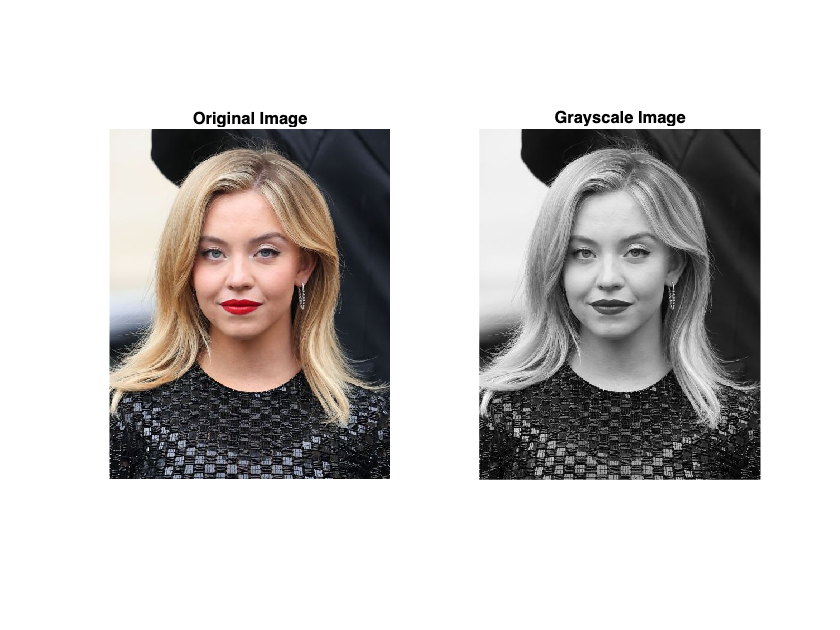

% To read test image and inputs in a matrix form
input_image  = imread('./assets/tut6-img.jpg');
% Convert to grayscale
img = rgb2gray(input_image);

figure;
subplot(1, 2, 1);
imshow(input_image);
title("Original Image");
subplot(1, 2, 2);
imshow(img);
title("Grayscale Image");

img = cast(img, "double");
N = size(img, 1);
M = size(img, 2);

### 1. Degrading Images

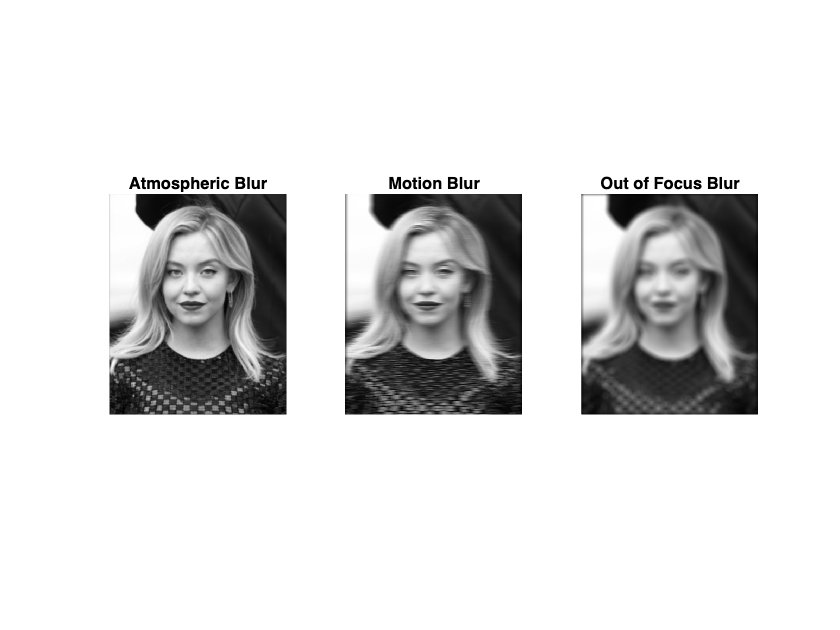

atm_blur_kernel = fspecial("gaussian", [10 10], 1.5);
mtn_blur_kernel = fspecial("motion", 20);
foc_blur_kernel = fspecial("disk", 10);

img_atm_blur = imfilter(img, atm_blur_kernel);
img_mtn_blur = imfilter(img, mtn_blur_kernel);
img_foc_blur = imfilter(img, foc_blur_kernel);

figure;
subplot(1, 3, 1);
imshow(img_atm_blur, []);
title("Atmospheric Blur");
subplot(1, 3, 2);
imshow(img_mtn_blur, []);
title("Motion Blur");
subplot(1, 3, 3);
imshow(img_foc_blur, []);
title("Out of Focus Blur");

### 2. Filtering

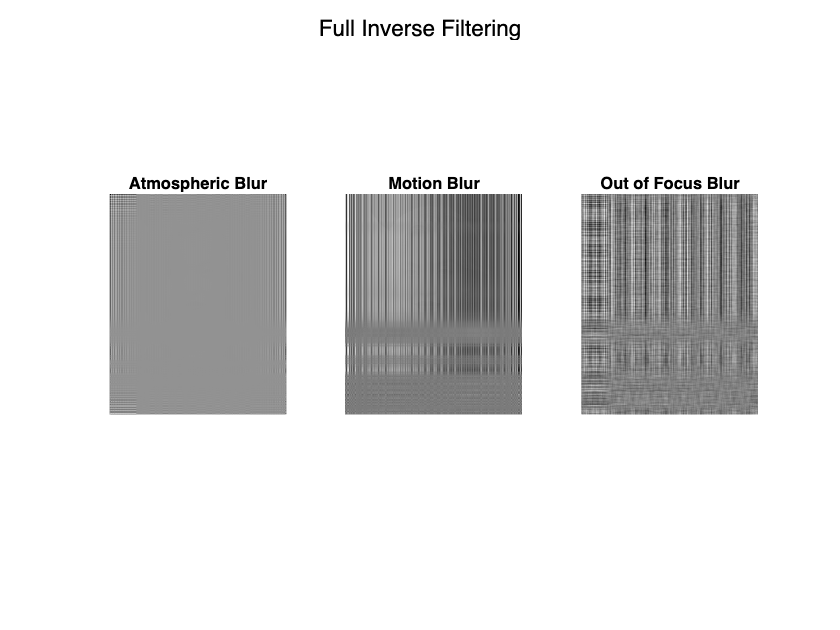

% Full Inverse Filter
% (specifying 0 for Noise-Signal-Ratio, which is the 3rd
% param of deconvwnr, is equivalent to ideal inverse filter)
atm_deblur_inv = deconvwnr(img_atm_blur, atm_blur_kernel, 0);
mtn_deblur_inv = deconvwnr(img_mtn_blur, mtn_blur_kernel, 0);
foc_deblur_inv = deconvwnr(img_foc_blur, foc_blur_kernel, 0);

display_results(atm_deblur_inv, mtn_deblur_inv, foc_deblur_inv, "Full Inverse Filtering");

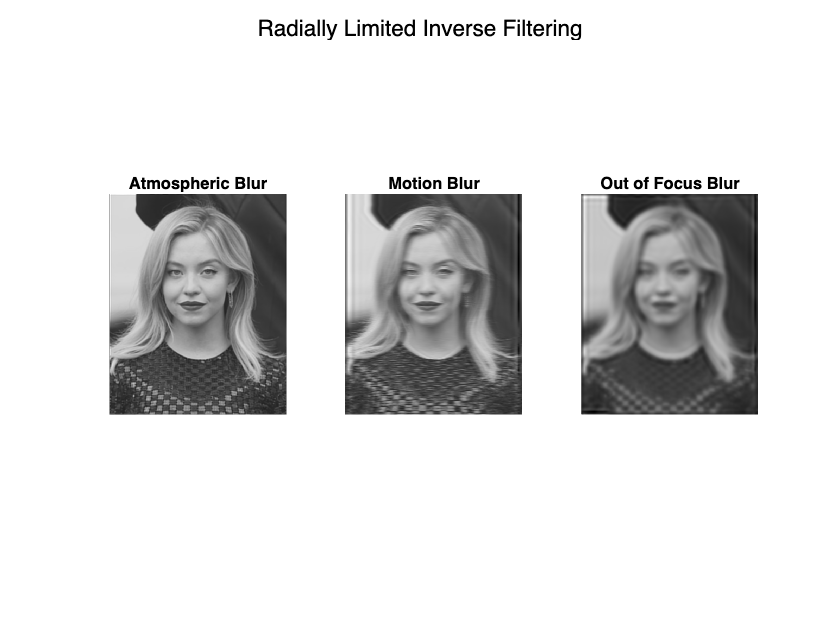

% Radially limited inverse filter
radius = 0.1;
atm_deblur_rad = deconvwnr(img_atm_blur, atm_blur_kernel, radius);
mtn_deblur_rad = deconvwnr(img_mtn_blur, mtn_blur_kernel, radius);
foc_deblur_rad = deconvwnr(img_foc_blur, foc_blur_kernel, radius);

display_results(atm_deblur_rad, mtn_deblur_rad, foc_deblur_rad, "Radially Limited Inverse Filtering");

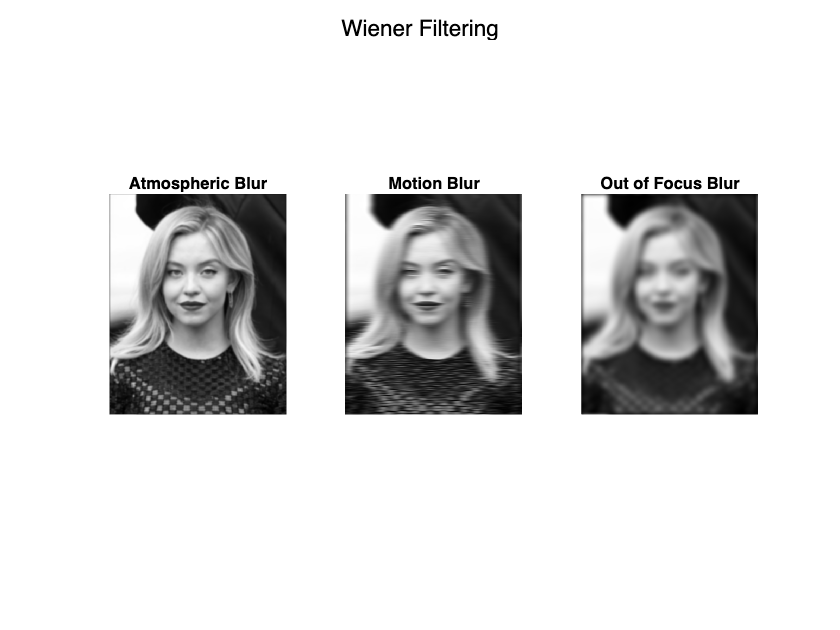

% Wiener Filter
NSR = 5;
atm_deblur_wnr = deconvwnr(img_atm_blur, atm_blur_kernel, NSR);
mtn_deblur_wnr = deconvwnr(img_mtn_blur, mtn_blur_kernel, NSR);
foc_deblur_wnr = deconvwnr(img_foc_blur, foc_blur_kernel, NSR);

display_results(atm_deblur_wnr, mtn_deblur_wnr, foc_deblur_wnr, "Wiener Filtering");

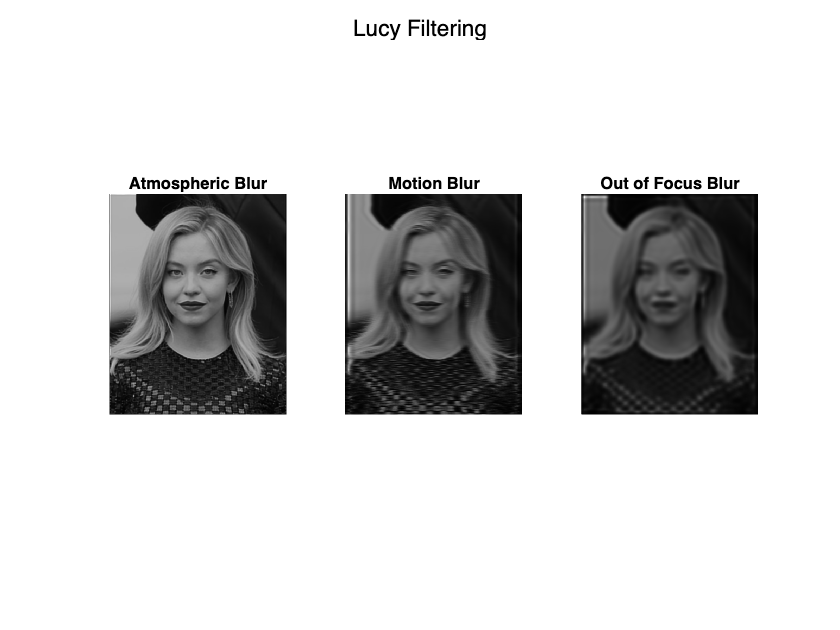

% Lucy Filter
iter = 5;
atm_deblur_lucy = deconvlucy(img_atm_blur, atm_blur_kernel, iter);
mtn_deblur_lucy = deconvlucy(img_mtn_blur, mtn_blur_kernel, iter);
foc_deblur_lucy = deconvlucy(img_foc_blur, foc_blur_kernel, iter);

display_results(atm_deblur_lucy, mtn_deblur_lucy, foc_deblur_lucy, "Lucy Filtering");

### 3. Varying Parameters

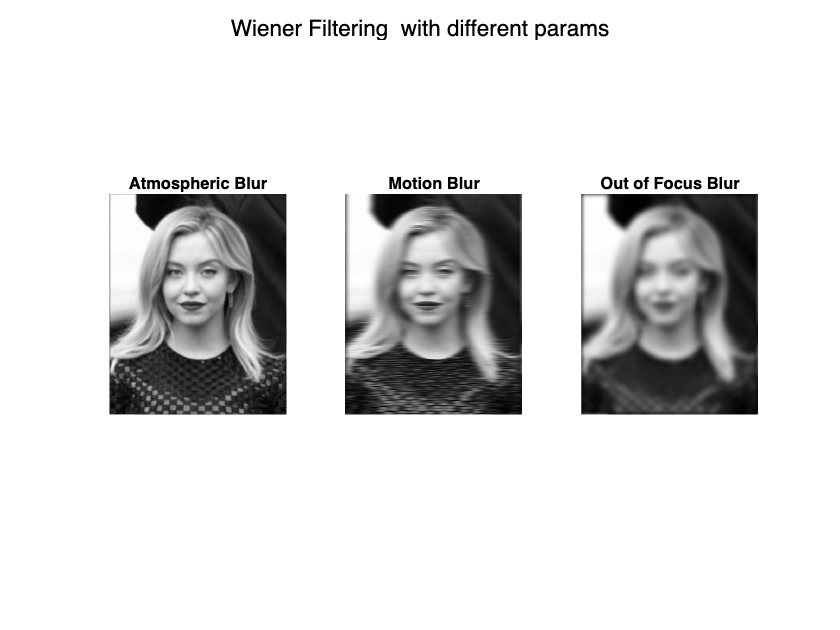

NSR = 30;
atm_deblur_diff_params = deconvwnr(img_atm_blur, atm_blur_kernel, NSR);
mtn_deblur_diff_params = deconvwnr(img_mtn_blur, mtn_blur_kernel, NSR);
foc_deblur_diff_params = deconvwnr(img_foc_blur, foc_blur_kernel, NSR);
display_results(atm_deblur_diff_params, mtn_deblur_diff_params,...
    foc_deblur_diff_params, "Wiener Filtering  with different params");

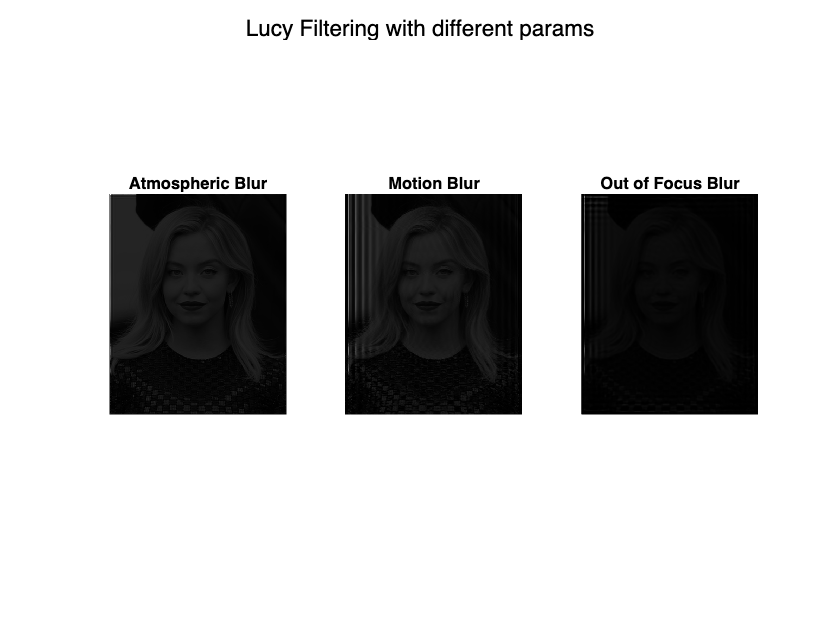

iter = 30;
atm_deblur_diff_params = deconvlucy(img_atm_blur, atm_blur_kernel, iter);
mtn_deblur_diff_params = deconvlucy(img_mtn_blur, mtn_blur_kernel, iter);
foc_deblur_diff_params = deconvlucy(img_foc_blur, foc_blur_kernel, iter);
display_results(atm_deblur_diff_params, mtn_deblur_diff_params,...
     foc_deblur_diff_params, "Lucy Filtering with different params");

### 4. Metrics

metrics0 = get_metrics(img, atm_deblur_inv);
metrics1 = get_metrics(img, atm_deblur_rad);
metrics2 = get_metrics(img, atm_deblur_wnr);
metrics3 = get_metrics(img, atm_deblur_lucy);
display(table(table(metrics0.', metrics1.', metrics2.', metrics3.',...
'VariableNames', {'Inverse', 'Radially Limited Inverse', 'Wiener', 'Lucy'},...
'RowNames', {'SNR', 'PSNR', 'MSE'}), 'VariableNames', {'Atmospheric Blur'}));

  3×1 table

                              Atmospheric Blur                          
    ____________________________________________________________________

             Inverse      Radially Limited Inverse    Wiener      Lucy  
            __________    ________________________    _______    _______
                                                                        
    SNR        -27.447             15.802              1.5274     17.293
    PSNR       -69.894            -26.644             -40.919    -25.153
    MSE     9.7582e+06             461.76               12356     327.56



metrics4 = get_metrics(img, mtn_deblur_inv);
metrics5 = get_metrics(img, mtn_deblur_rad);
metrics6 = get_metrics(img, mtn_deblur_wnr);
metrics7 = get_metrics(img, mtn_deblur_lucy);
display(table(table(metrics4.', metrics5.', metrics6.', metrics7.',...
'VariableNames', {'Inverse', 'Radially Limited Inverse', 'Wiener', 'Lucy'},...
'RowNames', {'SNR', 'PSNR', 'MSE'}), 'VariableNames', {'Motion Blur'}));

  3×1 table

                                Motion Blur                             
    ____________________________________________________________________

             Inverse      Radially Limited Inverse    Wiener      Lucy  
            __________    ________________________    _______    _______
                                                                        
    SNR        -20.184              14.45              1.4877     14.289
    PSNR        -62.63            -27.996             -40.959    -28.157
    MSE     1.8323e+06              630.4               12470     654.25



metrics8 = get_metrics(img, foc_deblur_inv);
metrics9 = get_metrics(img, foc_deblur_rad);
metrics10 = get_metrics(img, foc_deblur_wnr);
metrics11 = get_metrics(img, foc_deblur_lucy);
display(table(table(metrics8.', metrics9.', metrics10.', metrics11.',...
'VariableNames', {'Inverse', 'Radially Limited Inverse', 'Wiener', 'Lucy'},...
'RowNames', {'SNR', 'PSNR', 'MSE'}), 'VariableNames', {'Out of Focus Blur'}));

  3×1 table

                             Out of Focus Blur                          
    ____________________________________________________________________

             Inverse      Radially Limited Inverse    Wiener      Lucy  
            __________    ________________________    _______    _______
                                                                        
    SNR         -22.14             13.162              1.4621     13.302
    PSNR       -64.586            -29.284             -40.984    -29.144
    MSE     2.8747e+06              848.1               12544     821.08



### 5. Extreme Cases of Blur

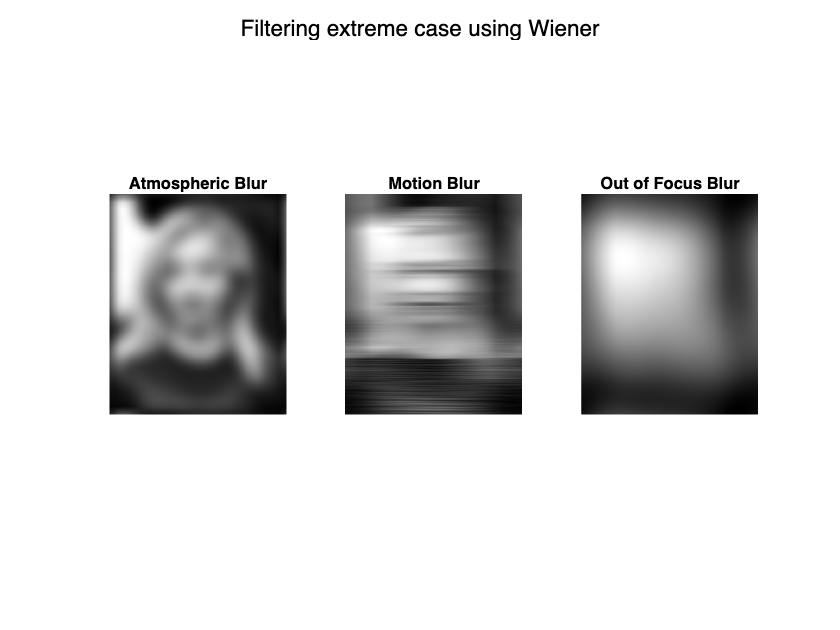

atm_extreme_blur_kernel = fspecial("gaussian", [50 50], 50);
mtn_extreme_blur_kernel = fspecial("motion", 150);
foc_extreme_blur_kernel = fspecial("disk", 100);

img_atm_blur_extreme = imfilter(img, atm_extreme_blur_kernel);
img_mtn_blur_extreme = imfilter(img, mtn_extreme_blur_kernel);
img_foc_blur_extreme = imfilter(img, foc_extreme_blur_kernel);

% Applying weiner and lucy filtering
NSR = 5;
atm_extreme_deblur_wnr = deconvwnr(img_atm_blur_extreme, atm_extreme_blur_kernel, NSR);
mtn_extreme_deblur_wnr = deconvwnr(img_mtn_blur_extreme, mtn_extreme_blur_kernel, NSR);
foc_extreme_deblur_wnr = deconvwnr(img_foc_blur_extreme, foc_extreme_blur_kernel, NSR);
iter = 10;
atm_extreme_deblur_lucy = deconvlucy(img_atm_blur_extreme, atm_extreme_blur_kernel, iter);
mtn_extreme_deblur_lucy = deconvlucy(img_mtn_blur_extreme, mtn_extreme_blur_kernel, iter);
foc_extreme_deblur_lucy = deconvlucy(img_foc_blur_extreme, foc_extreme_blur_kernel, iter);

display_results(atm_extreme_deblur_wnr, mtn_extreme_deblur_wnr,...
    foc_extreme_deblur_wnr, "Filtering extreme case using Wiener");

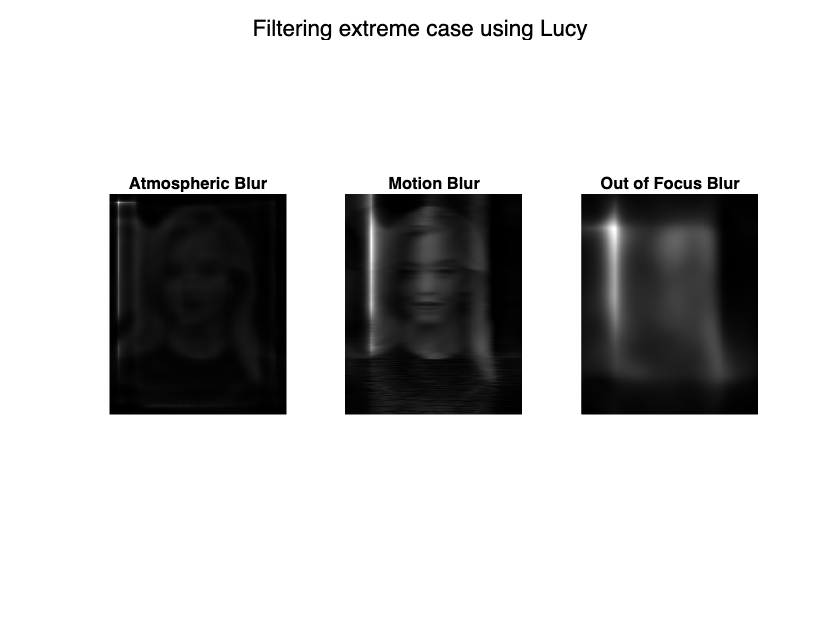

display_results(atm_extreme_deblur_lucy, mtn_extreme_deblur_lucy,...
    foc_extreme_deblur_lucy, "Filtering extreme case using Lucy");

In these extreme cases of degradation, the information loss caused by the blur is too severe for meaningful reconstruction to be possible using the deblurring process. Due to this reason, neither the Wiener nor Lucy algorithms are able to produce a suitably deblurred image from these degraded images.

function display_results(atm_res, mtn_res, foc_res, grp_title)
    figure;
    subplot(1, 3, 1);
    imshow(atm_res, []);
    title("Atmospheric Blur");
    subplot(1, 3, 2);
    imshow(mtn_res, []);
    title("Motion Blur");
    subplot(1, 3, 3);
    imshow(foc_res, []);
    title("Out of Focus Blur");
    sgtitle(grp_title);
end

function metrics = get_metrics(original, restored)
    SNR = snr(original, original - restored);
    PSNR = psnr(restored, original);
    MSE = immse(restored, original);
    metrics = [SNR, PSNR, MSE];
end